**Reading Files**

v3d_sample = load('/home/saeedghorbani/Projects/Data/MoVi/V3D/F/F_v3d_Subject_1.mat')
v3d_sample = v3d_sample.Subject_1_F
amass_sample = load('/home/saeedghorbani/Projects/Data/MoVi/AMASS/F_amass_Subject_1.mat')
amass_sample = amass_sample.Subject_1_F_amass

The v3d files are not trimmed to single motions by default. Use below function to augment the current sample with individual single motions

v3d_augmented = single_motions(v3d_sample)

This is the same for the videos. Only a single main video file is located in the dataset. Use the function below to crop the video file into single motions

video_name = "/home/saeedghorbani/Projects/Data/MoVi/V3D/F/F_Subject_1_L.avi"

video_name = "/home/saeedghorbani/Projects/Data/MoVi/V3D/F/F_Subject_1_L.avi"

single_videos(video_name, v3d_sample)

**Play motions motions by 3D joints**

Play a v3d sample

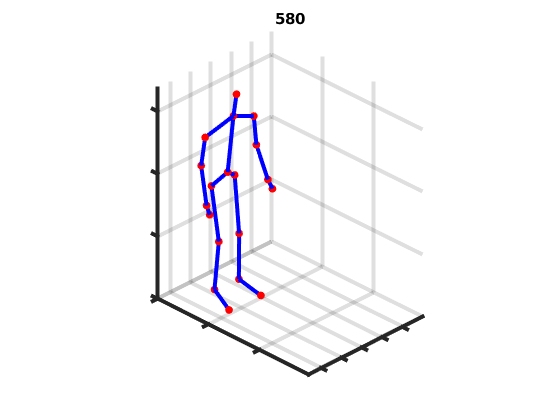

v3d_sample_motion = v3d_augmented.move{2, 1}.virtualMarkerLocation;
% Loading connections. Connections define the hierarchical skeleta
% structure
load('connections.mat')
play3DMotion(v3d_sample_motion, connections)

Play an amass sample

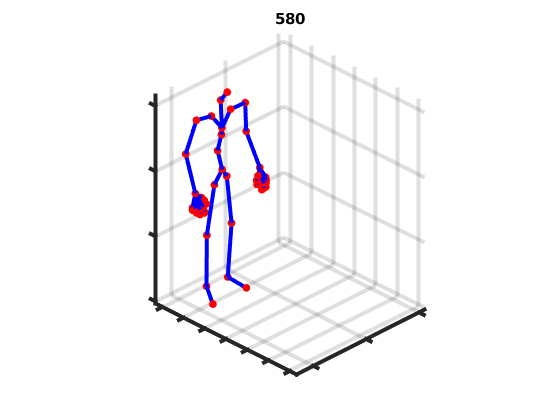

amass_sample_motion = amass_sample.move{1, 1}.jointsLocation_amass;
% Loading connections. Connections define the hierarchical skeleta
% structure
load('connections_amass.mat')
play3DMotion(amass_sample_motion, connections)

Playing video overlaid with joints and body mesh

Please note that body mesh is only available for amass data

By default, amass data does not include body mesh. To compute body mesh use utils.py/npz2movi function on original npz files. npz file can be downloaded from AMASS website ([https://amass.is.tue.mpg.de/](https://amass.is.tue.mpg.de/))

video_name = "/home/saeedghorbani/Projects/Data/MoVi/V3D/F/F_Subject_1_L1.avi"

video_name = "/home/saeedghorbani/Projects/Data/MoVi/V3D/F/F_Subject_1_L1.avi"

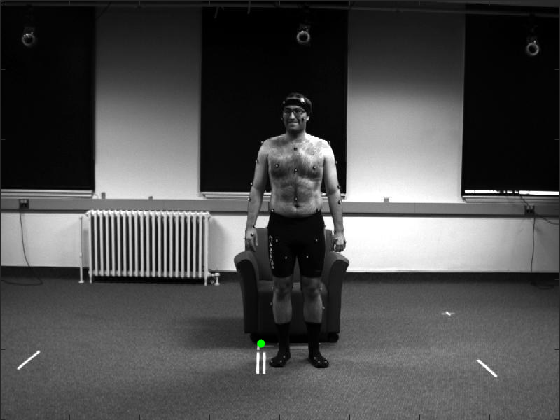

load('Subject_1_F_1_amass.mat')
load('cameraParams_PG1.mat')
load('Extrinsics_PG1.mat')
load('faces.mat')
display_overlay(jointsLocation, video_name, cameraParams, rotationMatrix, translationVector, faces, verts)